%Question 1
data= readtable("UNRATE.xlsx",'Sheet',2);
dates = datetime(data.observation_date, 'InputFormat', 'yyyy-MM-dd'); % Time index
Unemployment = data.UNRATE; 

%
mdl1=fitlm(lagmatrix(Unemployment,1),Unemployment) %start by NaN, end by 4.0 from Jan.2025, which is one period early than latest Feb.2025 

mdl1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)     0.1722      0.047206    3.6477    0.00027937
    x1             0.96983     0.0079568    121.89             0


Number of observations: 925, Error degrees of freedom: 923
Root Mean Squared Error: 0.413
R-squared: 0.942,  Adjusted R-Squared: 0.941
F-statistic vs. constant model: 1.49e+04, p-value = 0

%reg y_t on y_{t-1}
mdl2=fitlm(lagmatrix(Unemployment,2),Unemployment)

mdl2 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat      pValue  
                   ________    ________    ______    _________

    (Intercept)     0.3543     0.067478    5.2506    1.883e-07
    x1             0.93783      0.01137    82.481            0


Number of observations: 924, Error degrees of freedom: 922
Root Mean Squared Error: 0.59
R-squared: 0.881,  Adjusted R-Squared: 0.881
F-statistic vs. constant model: 6.8e+03, p-value = 0

mdl3=fitlm(lagmatrix(Unemployment,3),Unemployment)

mdl3 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)    0.52216      0.08148    6.4084    2.3443e-10
    x1             0.90835     0.013726    66.178             0


Number of observations: 923, Error degrees of freedom: 921
Root Mean Squared Error: 0.712
R-squared: 0.826,  Adjusted R-Squared: 0.826
F-statistic vs. constant model: 4.38e+03, p-value = 0

%plug in Method
ur=Unemployment(end);
alpha_1 = mdl1.Coefficients.Estimate(1); % Intercept
beta_1 = mdl1.Coefficients.Estimate(2); % AR(1) coefficient
alpha_2=(1+beta_1)*alpha_1;
beta_2=beta_1^2;
alpha_3=(1+beta_1+beta_1^2)*alpha_1;
beta_3=beta_1^3;
ur_1=alpha_1+beta_1*ur;
ur_2=alpha_2+beta_2*ur;
ur_3=alpha_3+beta_3*ur;
display(ur_1);

ur_1 = 4.1485

display(ur_2)

ur_2 = 4.1955

display(ur_3);

ur_3 = 4.2411

%iteration method
%3step-ahead, iterative (manual)
g=Unemployment(end); p_iter=zeros(3,1); %vector of point forecasts
for i=1:3
p_iter(i,1)=predict(mdl1,g);
g=p_iter(i,1);
display(p_iter(i,1));
end

    4.1485

    4.1955

    4.2411



%Direct methond
for i=1:3
mdl=fitlm(lagmatrix(Unemployment,i),Unemployment);
Unemployment_p = predict(mdl,Unemployment);
Unemployment_f(i,1)=Unemployment_p(length(Unemployment_p),1);
display(Unemployment_f(i,1));
end

    4.1485

    4.1994

    4.2464



By the plug in method, we have 4.1485 in the first step, 4.1955 in the second step, 4.2411 in the third step. 

By the iteration method, we have 4.1485 in the first step, 4.1955 in the second step, 4.2411 in the third step. 

By the direct method, we have 4.1485 in the first step, 4.1994 in the second step, 4.2464 in the third step. 

The key finding is that we find that the predictions for the plug in method and the iteration method are the same. This is because in the iteration are equivalent to the plug in method.$y_{T+2|T}=\alpha+\beta(y_{T+1|T})=\alpha+\beta(\alpha+\beta y_T)=(1+\beta)\alpha+\beta^2 y_T$ and$y_{T+3|T}=\alpha+\beta(y_{T+2|T})=\alpha+\beta(\alpha+\beta y_{T+1|T})=(1+\beta)\alpha+\beta^2 y_{T+1|T}=(1+\beta)\alpha+\beta^2 (\alpha +\beta y_{T})=(1+\beta+\beta^2)\alpha+\beta^3 y_{T}$

question 2

a. i) $E(y_t)=\alpha+\beta E(y_{t-1})$   $\mu=\alpha+\beta\cdot \mu$   $\mu=\frac{\alpha}{1-\beta}=4/3， \beta=1/4<0, \alpha=1$

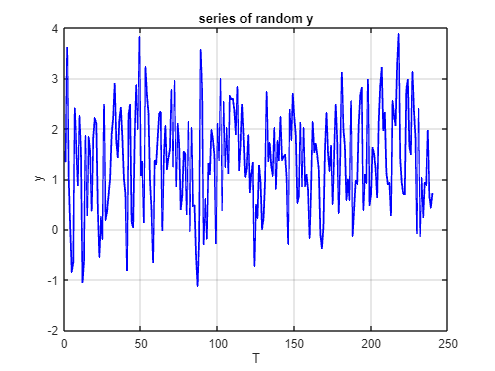

%ii
% Set parameters
T = 240; % Length of time series
rng(514); % Set seed for reproducibility
alpha_a=1;
beta_a=0.25;
% Compute unconditional mean
    mu = alpha_a / (1 - beta_a);
    
    % Simulate AR(1) process
    y = zeros(T,1);
    y(1) = mu; % Set initial value as the unconditional mean
    epsilon = randn(T,1); % i.i.d. white noise ~ N(0,1)
    
    for t = 2:T
        y(t) = alpha_a + beta_a * y(t-1) + epsilon(t);
    end

% graph
figure;
plot(y, 'b', 'LineWidth', 1.5);
hold on;
xlabel('T'); ylabel('y');
title('series of random y');
grid on;


%part iii Estimate AR(1) model using OLS
y_lag = lagmatrix(y,1); % Create lagged variable
valid_idx = ~isnan(y_lag); % Remove NaNs for regression
mdl = fitlm(y_lag(valid_idx), y(valid_idx));
    
% Display estimated coefficients
est_alpha_a = mdl.Coefficients.Estimate(1);
est_beta_a = mdl.Coefficients.Estimate(2);
    

fprintf('Estimated alpha: %.4f (True: %.4f)\n', est_alpha_a, alpha_a);

Estimated alpha: 1.0430 (True: 1.0000)


fprintf('Estimated beta: %.4f (True: %.4f)\n', est_beta_a, beta_a);

Estimated beta: 0.2322 (True: 0.2500)


 The real value and the estimation is close 

b i) $E(y_t)=\alpha+\beta E(y_{t-1})$,$\mu=\alpha+\beta\cdot \mu$,$\mu=\frac{\alpha}{1-\beta}=100, \alpha=10,\beta=0.9<1
$

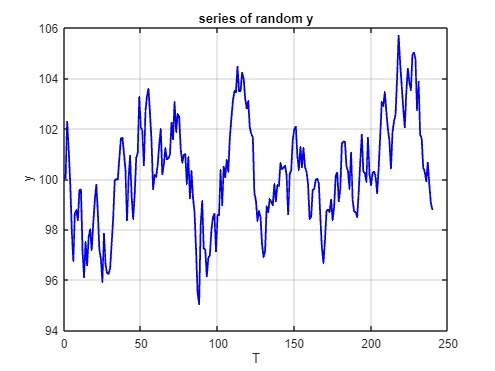


%b
%ii
% Set parameters
T = 240; % Length of time series
rng(514); % Set seed for reproducibility
alpha_b=10;
beta_b=0.9;
% Compute unconditional mean
    mu = alpha_b / (1 - beta_b);
    
    % Simulate AR(1) process
    y = zeros(T,1);
    y(1) = mu; % Set initial value as the unconditional mean
    epsilon = randn(T,1); % i.i.d. white noise ~ N(0,1)
    
    for t = 2:T
        y(t) = alpha_b + beta_b * y(t-1) + epsilon(t);
    end

% graph
figure;
plot(y, 'b', 'LineWidth', 1.5);
hold on;
xlabel('T'); ylabel('y');
title('series of random y');
grid on;


%Check the Typo
%part iii Estimate AR(1) model using OLS
y_lag = lagmatrix(y,1); % Create lagged variable
valid_idx = ~isnan(y_lag); % Remove NaNs for regression
mdl = fitlm(y_lag(valid_idx), y(valid_idx));
    
% Display estimated coefficients
est_alpha_b = mdl.Coefficients.Estimate(1);
est_beta_b = mdl.Coefficients.Estimate(2);
    
fprintf('Estimated alpha: %.4f (True: %.4f)\n', est_alpha_b, alpha_b);

Estimated alpha: 11.7481 (True: 10.0000)


fprintf('Estimated beta: %.4f (True: %.4f)\n', est_beta_b, beta_b);

Estimated beta: 0.8827 (True: 0.9000)


The estimation and the real value is close.

c. $E(y_t)=\alpha+\beta E(y_{t-1})$,$\mu=\alpha+\beta\cdot \mu$,$\mu=\frac{\alpha}{1-\beta}=0, \alpha=0,\beta=-0.5$

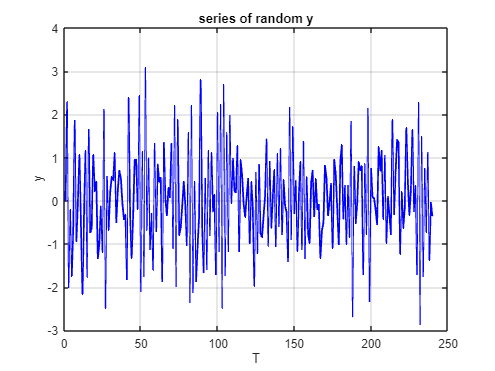

%c
%ii
% Set parameters
T = 240; % Length of time series
rng(514); % Set seed for reproducibility
alpha_c=0;
beta_c=-0.5;
% Compute unconditional mean
    mu = alpha_c / (1 - beta_c);
    
    % Simulate AR(1) process
    y = zeros(T,1);
    y(1) = mu; % Set initial value as the unconditional mean
    epsilon = randn(T,1); % i.i.d. white noise ~ N(0,1)
    
    for t = 2:T
        y(t) = alpha_c + beta_c * y(t-1) + epsilon(t);
    end
% graph
figure;
plot(y, 'b', 'LineWidth', 1.5);
hold on;
xlabel('T'); ylabel('y');
title('series of random y');
grid on;


%part iii Estimate AR(1) model using OLS
y_lag = lagmatrix(y,1); % Create lagged variable
valid_idx = ~isnan(y_lag); % Remove NaNs for regression
mdl = fitlm(y_lag(valid_idx), y(valid_idx));
    
% Display estimated coefficients
est_alpha_c = mdl.Coefficients.Estimate(1);
est_beta_c = mdl.Coefficients.Estimate(2);
    

fprintf('Estimated alpha: %.4f (True: %.4f)\n', est_alpha_c, alpha_c);

Estimated alpha: 0.0195 (True: 0.0000)


fprintf('Estimated beta: %.4f (True: %.4f)\n', est_beta_c, beta_c);

Estimated beta: -0.5549 (True: -0.5000)


The estimation and the real value are close.

question 3

a. Proof: Given that $y_t=\beta y_{t-1}+\epsilon_t
$,$y_{T+1|T}=E(y_{T+1}|y_T)=\beta \cdot y_T$, $y_{T+2|T}=E(y_{T+2}|y_T)=\beta \cdot y_{T+1|T}=\beta \cdot E(y_{T+1}|T)$. This is equivalent to $\beta \cdot \beta \cdot y_T=\beta^2\cdot y_T$. Inductively, $y_{T+h|T}=E(y_{T+h}|y_T)=\beta(\beta y_{T+h-2|T})=\beta^2E(y_{T+h-2})=\beta^h\cdot y_T$(q.e.d)

b. Proof: Given that $y_t=\beta y_{t-1}+\epsilon_t
$,$u_{T+1|T}=y_{T+1}-E(y_{T+1}|y_T)=\beta y_T+\epsilon_{T+1}-\beta y_T=\epsilon_{T+1}$,

 
$$u_{T+2|T}=y_{T+2}-E(y_{T+2}|y_T)=\beta^2 y_T+\beta\epsilon_{T+1}+\epsilon_{T+2}-\beta^2 y_T=\beta\epsilon_{T+1}+\epsilon_{T+2}$$


Inductively, we then have $u_{T+h|T}=y_{T+h}-y_{T+h|T}=y_{T+h}-E(y_{T+h}|T)$. This is equivalent to 

$\beta^h\cdot y_T+\beta\epsilon_{T+h-1}+\cdots+\beta^{h-1}\epsilon_{T+1}+\epsilon_{T+h}-\beta^h\cdot y_T$ Furthermore, we have $\beta\epsilon_{T+h-1}+\cdots+\beta^{h-1}\epsilon_{T+1}+\epsilon_{T+h}$.(q.e.d)

c. Proof: Given that $\sigma^2_1=Var(y_{T+1})=Var(\beta y_{T}+\epsilon_{T+1})=Var(\epsilon_{T+1})= \sigma^2$

 
$$\sigma^2_2=Var(y_{T+2})=Var(\beta (\beta y_{T}+\epsilon_{T+1})+\epsilon_{T+2})=\beta^2Var(\epsilon_{T-1})+Var(\epsilon_T)= (1+\beta^2)\sigma^2$$


Inductively,  we have $var(\beta\epsilon_{T+h-1}+\cdots+\beta^{h-1}\epsilon_{T+1}+\epsilon_{T+h})=\sigma^2+\beta^2\sigma^2+\cdots+\beta^{2(h-1)}\sigma^2$(q.e.d)

d Proof: Because the AR(1) process is equivalent to $y_{T+1}=\beta y_{T}+\epsilon_{T+1}=\sum^\infty_{i=0}\beta^i\epsilon_{t-i}$. $var(y_T)=Var(\sum^\infty_{i=0}\beta^i \epsilon_{t-i})=\sigma^2\sum^\infty_{i=0}\beta^{2i}=\frac{\sigma^2}{1-\beta^2}$ by lecture 13 material.  As h increases to infinity, $var(\beta\epsilon_{T+h-1}+\cdots+\beta^{h-1}\epsilon_{T+1}+\epsilon_{T+h})=\sigma^2+\beta^2\sigma^2+\cdots+\beta^{2(h-1)}\sigma^2$, this will turn into an infinite geometric series. Specifically if $\beta< |1|$we have $\lim_{h \to \infty} \sigma^2_h =\frac{\sigma^2}{1-\beta^2}$ which is equivalent to the unconditional variance of AR(1).

This holds because $Var(y_T)=Var(\beta y_{T-1}+\epsilon),Var(y_T)=\beta^2Var(y_{T-1})+2\beta Cov(y_{T-1},\epsilon)+Var(\epsilon)$

$\sigma_y^2=\beta^2\sigma^2_y+\sigma^2$ $\sigma_y^2=\frac{\sigma^2}{1-\beta^2}$(q.e.d)

4 Proof: Based on the fact that $\sigma^2_2=Var(y_{T+2})=Var(\beta (\beta y_{T}+\epsilon_{T+1})+\epsilon_{T+2})=\beta^2Var(\epsilon_{T-1})+Var(\epsilon_T)= (1+\beta^2)\sigma^2$ is greater than  $\sigma^2_1=Var(y_{T+1})=Var(\beta y_{T}+\epsilon_{T+1})=Var(\epsilon_{T+1})= \sigma^2$ because$\beta^2>0$ . Therefore the statement is true.(q.e.d)